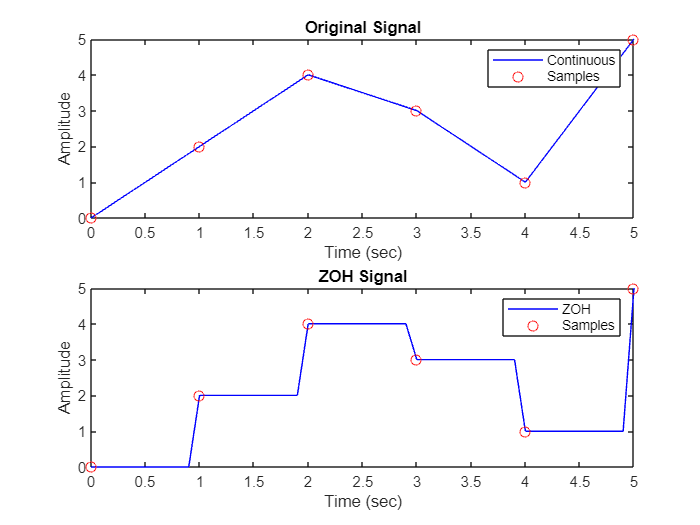

% Input signal
y = [0, 2, 4, 3, 1, 5];
time = [0, 1, 2, 3, 4, 5];

% Sampling rate
fs = 10; % Hz

% Time vector for ZOH signal
t_zoh = 0:1/fs:max(time);

% ZOH signal
y_zoh = interp1(time, y, t_zoh, 'previous');

% Plot original and ZOH signals
t_cont = 0:0.001:max(time);
y_cont = interp1(time, y, t_cont, 'linear');

subplot(2,1,1);
plot(t_cont, y_cont, 'b-', time, y, 'ro');
title('Original Signal');
xlabel('Time (sec)');
ylabel('Amplitude');
legend('Continuous', 'Samples');

subplot(2,1,2);
plot(t_zoh, y_zoh, 'b-', time, y, 'ro');
title('ZOH Signal');
xlabel('Time (sec)');
ylabel('Amplitude');
legend('ZOH', 'Samples');


t = .99;
y_t = interp1(t_zoh, y_zoh, t, 'previous');
fprintf('Value of ZOH signal at t = %.2f seconds: %.2f\n', t, y_t);

Value of ZOH signal at t = 0.99 seconds: 0.00
